%Are the Roundworms Alive or Dead?

imds = imageDatastore("WormImages"); %To store the images from the folder called WormImages

%Get the known classifications from a file and use these as the image labels
groundtruth = readtable("WormData.csv"); 
imds.Labels = categorical(groundtruth.Status);

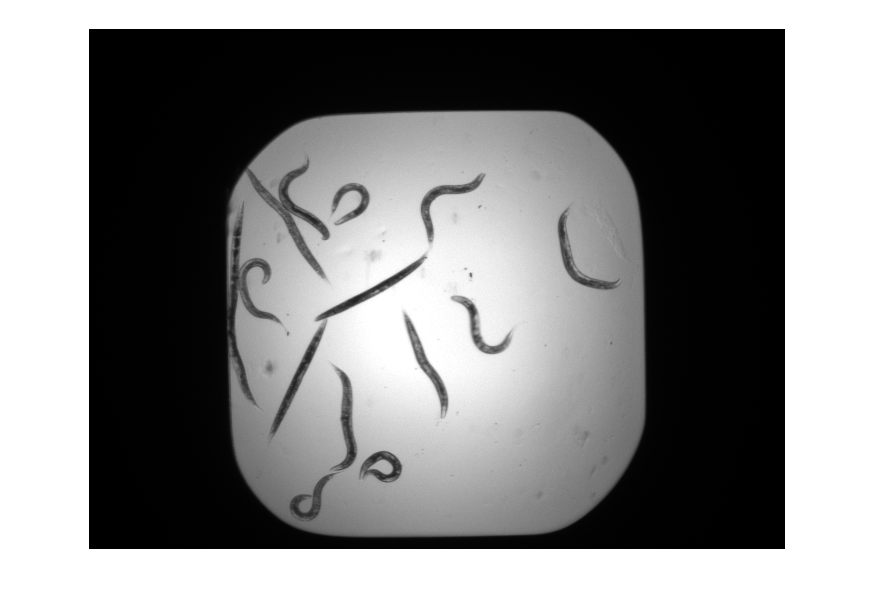

%Showing some images just to check if our images are available
imshow(readimage(imds,1))

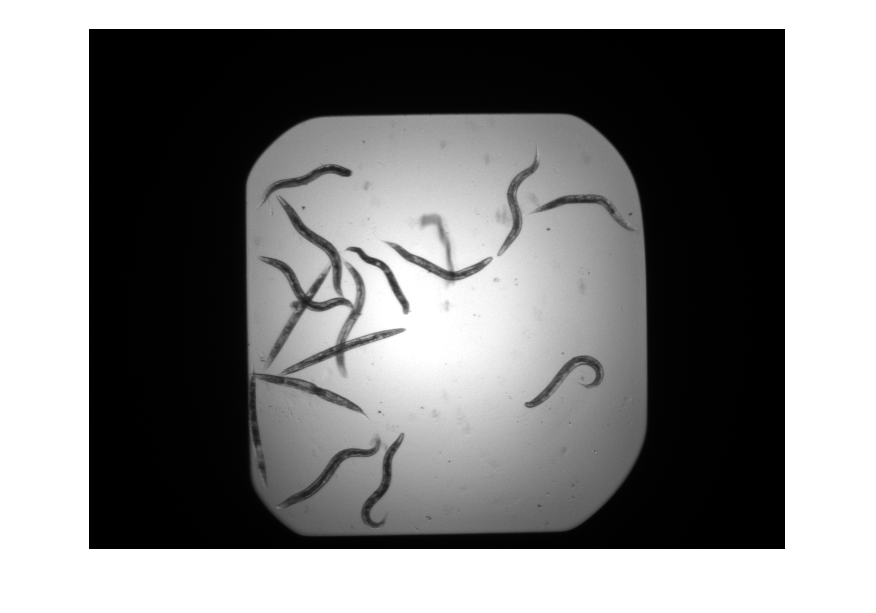

imshow(readimage(imds,2))

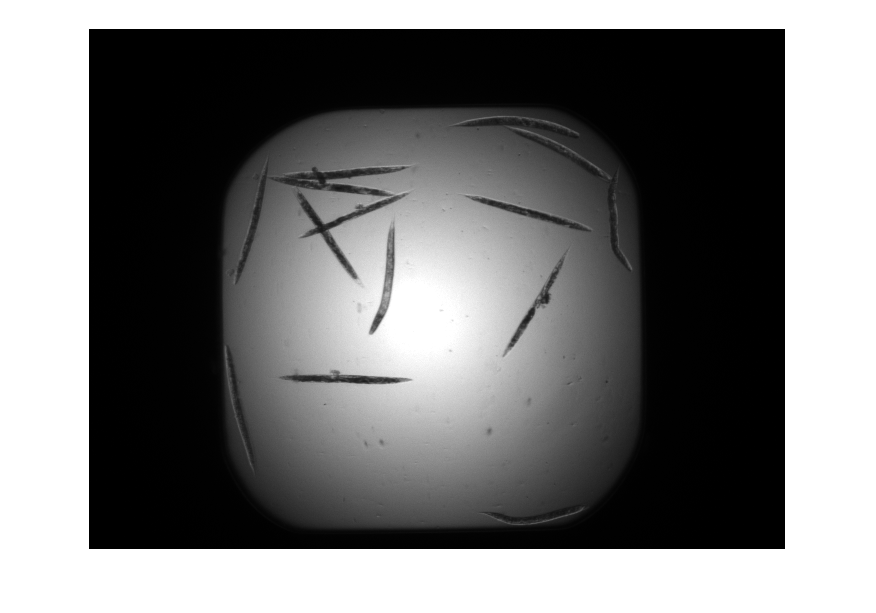

imshow(readimage(imds,13))

%Spliting images into test and train zone 

[trainImgs,testImgs] = splitEachLabel(imds,0.6,"randomized");
%60% of the images have been allocated to the train zone

trainaug = augmentedImageDatastore([224 224],trainImgs,"ColorPreprocessing","gray2rgb")

trainaug =   augmentedImageDatastore with properties:

             NumObservations: 56
                       Files: {56×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: 'none'
          ColorPreprocessing: 'gray2rgb'
                  OutputSize: [224 224]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0


testaug = augmentedImageDatastore([224 224],testImgs,"ColorPreprocessing","gray2rgb")

testaug =   augmentedImageDatastore with properties:

             NumObservations: 37
                       Files: {37×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: 'none'
          ColorPreprocessing: 'gray2rgb'
                  OutputSize: [224 224]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0


net =   DAGNetwork with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'output'}


net = googlenet
lgraph = layerGraph(net)

lgraph =   LayerGraph with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'output'}


%Training our images with CNN
opts = trainingOptions("sgdm","InitialLearnRate",0.001)

opts =   TrainingOptionsSGDM with properties:

                    Momentum: 0.9000
            InitialLearnRate: 1.0000e-03
           LearnRateSchedule: 'none'
         LearnRateDropFactor: 0.1000
         LearnRateDropPeriod: 10
            L2Regularization: 1.0000e-04
     GradientThresholdMethod: 'l2norm'
           GradientThreshold: Inf
                   MaxEpochs: 30
               MiniBatchSize: 128
                     Verbose: 1
            VerboseFrequency: 50
              ValidationData: []
         ValidationFrequency: 50
          ValidationPatience: Inf
                     Shuffle: 'once'
              CheckpointPath: ''
        ExecutionEnvironment: 'auto'
                  WorkerLoad: []
                   OutputFcn: []
                       Plots: 'none'
              SequenceLength: 'longest'
        SequencePaddingValue: 0
    SequencePaddingDirection: 'right'
        DispatchI

wormsnet = trainNetwork(trainaug,lgraph_1,opts)

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:03:22 |       53.57% |       1.4959 |          0.0010 |
|      30 |          30 |       00:49:49 |      100.00% |       0.0082 |          0.0010 |
|========================================================================================|


wormsnet =   DAGNetwork with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'classoutput'}


pred1 = classify(wormsnet,testaug)

pred1 = 37×1 categorical array
     alive 
     dead 
     dead 
     dead 
     dead 
     dead 
     alive 
     alive 
     alive 
     alive 
     alive 
     alive 
     dead 
     dead 
     dead 
     alive 
     alive 
     alive 
     alive 
     alive 
     alive 
     dead 
     dead 
     dead 
     dead 
     dead 
     dead 
     alive 
     alive 
     alive 


pred2 = classify(wormsnet,trainaug)

pred2 = 56×1 categorical array
     alive 
     alive 
     alive 
     alive 
     alive 
     alive 
     alive 
     alive 
     alive 
     alive 
     alive 
     dead 
     dead 
     dead 
     dead 
     dead 
     dead 
     dead 
     alive 
     alive 
     alive 
     alive 
     alive 
     alive 
     dead 
     dead 
     dead 
     dead 
     dead 
     dead 


ans = 1